# **PESTools - Example 022 - Fitting PES spectra**

## Author: PCC

The example shows how to use PESTools to fit the data from an PES experiment using a model that consists of a linear combination of N curves and a global optimisation method to minimise residuals.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

For external data files, all you need to do is define the **x-axis (binding energy)** and **y-axis (intensity) **and all the fitting tools are available to use. This means you can in principle import any type of data you like, even a text file. To be compatible, all you need to do is define a matlab struct(), for example 'PES_dat{1}', with **two** fields:

- Define the **x-axis data** as:    PES_dat{1}**.xdat**

- Deine the **y-axis data **as:     PES_dat{1}**.ydat**

close all; clear all;
pp          = plot_props();
data_path   = 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\';
save_path   = 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\';

# **PES Data Processing**

**(A) Loading in the PES data files**

file_names      = {...
    '020_XPS_In4d_hv=550eV.h5',...
    };
pes_dat = cell(1,length(file_names));
for i = 1:length(file_names); pes_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ARPES data...


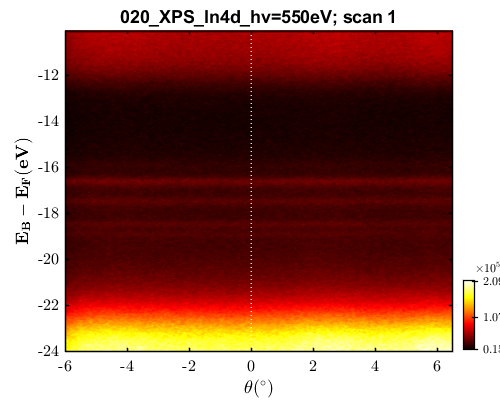

view_data(pes_dat{1});

**(B) Loading in the Fermi edge reference via gold / copper**

Note, that all PES data should come with a Fermi-edge reference so that the binding energy scale can be properly calibrated.

% Loading in the data files
file_names_ef      = {...
    '020_XPS_In4d_hv=550eV_EF.h5',...
    };
pes_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); pes_ref{i} = load_adress_data(file_names_ef{i}, data_path); end

Loading ARPES data...


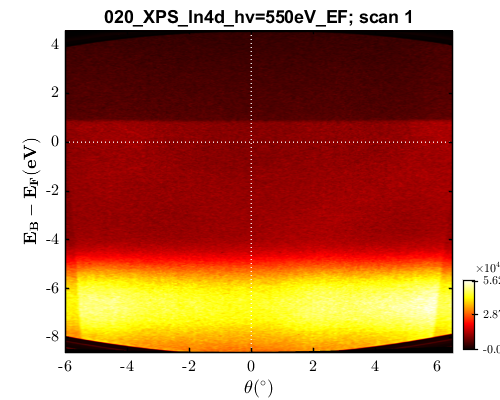

view_data(pes_ref{1});

**(C) Binding energy alignment to the reference data**

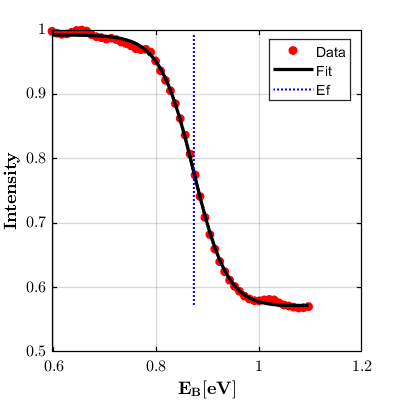

alignType   = "fit2ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.85;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.25;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(pes_dat)
    pes_dat{i}  = align_energy(pes_dat{i}, align_args, pes_ref{i}); 
end

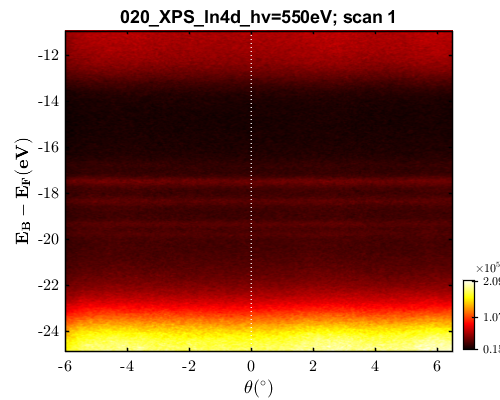

view_data(pes_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Extract the PES data by angle-integrating the ARPES spectrum**

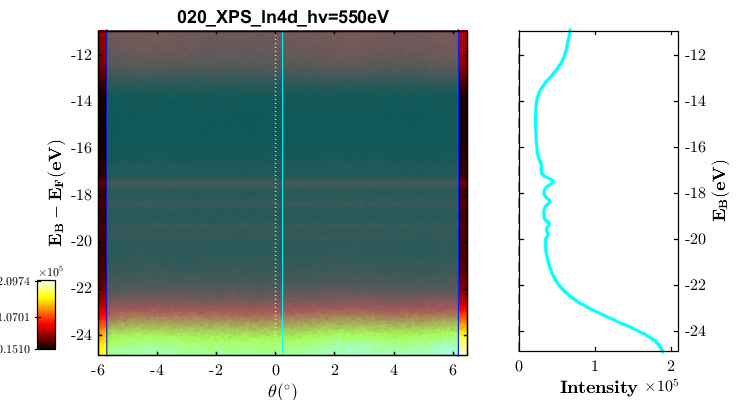

cutWin          = 0.95*[min(pes_dat{1}.tht(:)), max(pes_dat{1}.tht(:))];    % Integration window of the cut to be made.
cutN            = 1;                                                        % Single, constant value that determines the total number of line profiles to extract
xps_args        = {cutWin, cutN};
for i = 1:length(pes_dat)
    [pes_dat{i}, ~]     = pes_extract_data(pes_dat{i}, xps_args);
end

if length(pes_dat{i}) > 1; pes_dat = [pes_dat{:}]; end
view_data(pes_dat{1});

**(E) Comparing the peak positions vs measurements**

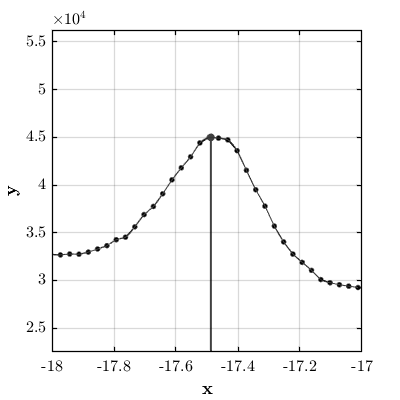

1) x = -17.49 eV, y = 45000.23 


% -- Extracting the energy and intensity of the peak positions
PES_xVal    = [];
PES_yVal    = [];
xWin            = -17.5 + [-0.50, 0.50];
for i = 1:length(pes_dat); [PES_xVal(i), PES_yVal(i)] = find_peak_loc(pes_dat{i}.xdat, pes_dat{i}.ydat, xWin, 'spline'); end

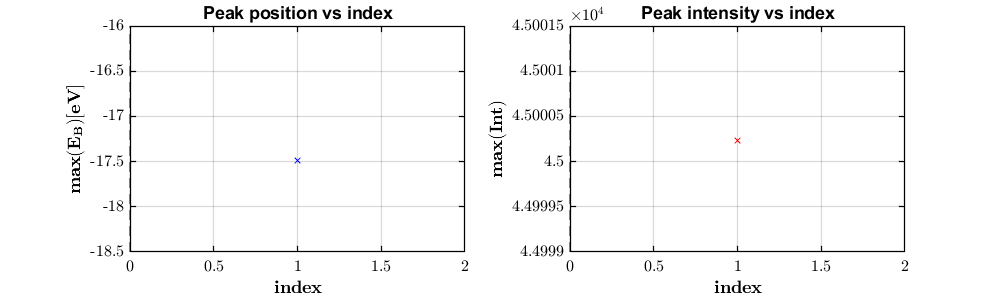

% -- Plotting the comparison
fig1 = figure(); 
fig1.Position(3) = 2.0*500;
fig1.Position(4) = 1.0*300;
% -- Plotting the Peak Eb position vs Photon Energy
subplot(121); hold on;
plot(1:length(PES_xVal), PES_xVal, 'bx-');
% - Formatting the figure
% axis padded; 
gca_props(); grid on;
xlabel('$$ \bf  index $$', 'Interpreter', 'latex');
ylabel('$$ \bf  max(E_B) [eV] $$', 'Interpreter', 'latex');
title("Peak position vs index");
% -- Plotting the Peak Intensity vs Photon Energy
subplot(122); hold on;
plot(1:length(PES_xVal), PES_yVal, 'rx-');
% - Formatting the figure
% axis padded; 
gca_props(); grid on;
xlabel('$$ \bf  index $$', 'Interpreter', 'latex');
ylabel('$$ \bf  max(Int) $$', 'Interpreter', 'latex');
title("Peak intensity vs index");

**(F) Crop around the region of interest**

As you can see from above, the background is quite large, so we would like to crop the data over the binding energy range of interest. 

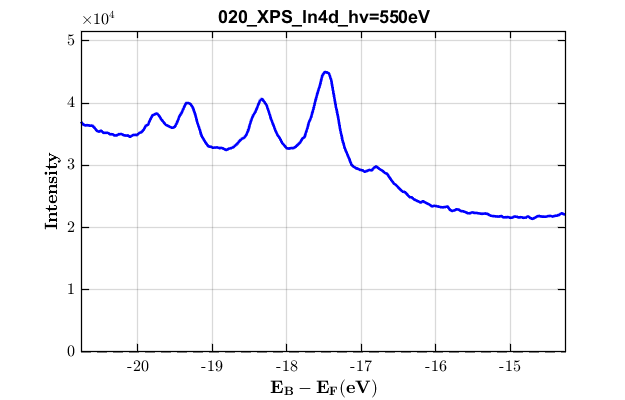

ebLims = -17.5 + [-3.25, 3.25];
for i = 1:length(pes_dat)
    [~, pes_dat{i}.xdat, pes_dat{i}.ydat] = data_crop2D([], pes_dat{i}.xdat, pes_dat{i}.ydat, [], ebLims);
end
view_pes_data(pes_dat{1});

**(G) Normalisation of the PES spectrum**

One of the most common processing that is done on PES data is to renormalise the data so that its minimum is at zero and maximum at one. Although not necessary, we do this here as it simplifies the initial conditions of the PES fitting algorithm to reasonable values of intensities. To normalise the PES data, we use the 'normalise_xps()' function and define a peak that we treat as the normalisation peak. 

ans = "xval = -17.49 eV, yval = 23601.51"

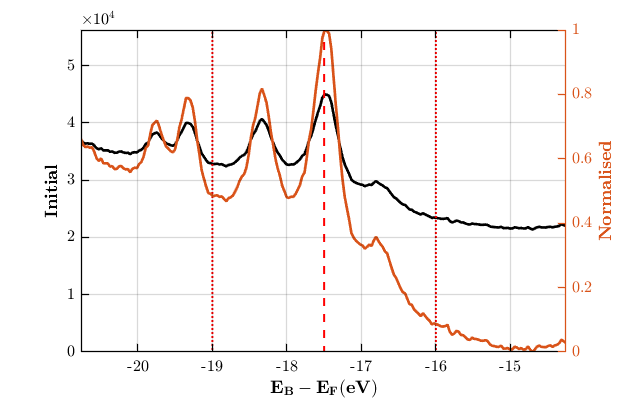

eWin            = -17.5;        % approximate Eb position of a peak in the spectrum to normalise to.
dEWin           = 1.5;          % can be empty []. Single, constant value that defines the width of the approximate Eb position
norm_args    = {eWin, dEWin};
for i = 1:length(pes_dat)
    pes_dat{i}.ydat = pes_norm2peak(pes_dat{i}.xdat, pes_dat{i}.ydat, norm_args, 1);
end

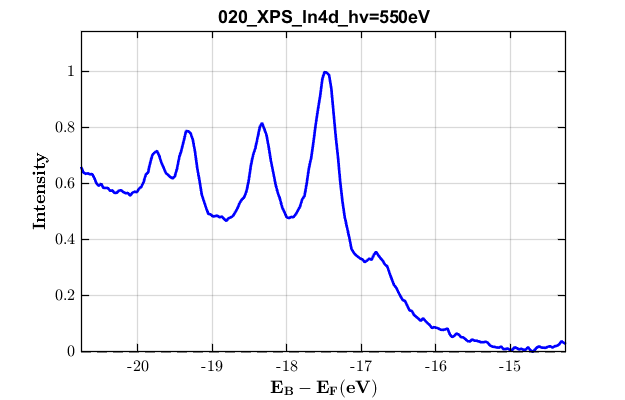

view_pes_data(pes_dat{1});

**(H) Final data structure that will be fitted**

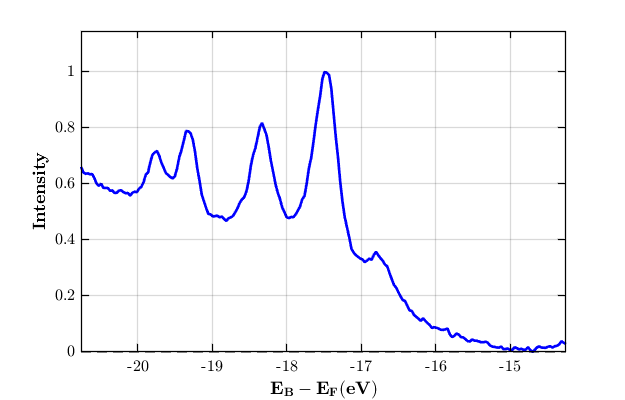

ans = struct with fields:
       FileName: '020_XPS_In4d_hv=550eV'
         H5file: '020_XPS_In4d_hv=550eV.h5'
           Type: "Eb(k)"
           meta: [1×1 struct]
       raw_data: [467×391 double]
        raw_tht: [1×391 double]
         raw_eb: [467×1 double]
            deb: 0.0500
             hv: 550
            dhv: 0.0750
           tltM: 0
           thtM: 0
           Temp: 5.5000
      eb_shifts: {[0.8728]}
    eb_ref_file: '020_XPS_In4d_hv=550eV_EF'
             eb: [467×391 double]
            tht: [467×391 double]
        IsoType: "XPS"
       xps_args: {[-5.7000 6.1750]  [1]}
         cutWin: [-5.7000 6.1750]
           cutN: 1
           xdat: [218×1 double]
           ydat: [218×1 double]


view_pes_data(pes_dat); pes_dat{1}

# **PES Fitting Algorithm**

The PESTools functions offer a host of different line-shapes and background that you can use for fitting PES spectra. Here is a line of all available functions:

- **For PES curves:** **Gaussian**, **Lorentzian**, **Voigt**, **asymmetrical Voigt **and **Doniach-Sunjic** functions are available.

- **For Backgrounds:** **Linear**, **Shirley** and **Offset Shirley** functions are available

The general objective of fitting PES data is to define an initial photoelectron spectrum that provides a reasonable first guess and then run an optimisation procedure to hone in to the best fit solution. Here, the general procedures are listed below;

- Define the shape and properties of the *N* PES components to be fitted

- Define the type of background to be used

- Preview the initial conditions of the PES curve fit model vs data

- If you are happy with the initial guess, use 'xps_solver()' to run the optimisation algorithm

**(A) Initialising the PES data to be fitted**

pes_fit               = struct();
pes_fit.FileName      = file_names;
pes_fit.repeats       = length(pes_dat);
pes_fit.data          = pes_dat;

**(B) Initialising the shape and properties of the PES components to be fitted**

iparams = {};
% DEFINING THE TYPES OF CURVES TO BE USED
cTYPE   = ["sGLA";  "sGLA";  "sGLA";  "sGLA"];  % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
% 1 - DEFINING THE INITIAL CONDITIONS OF THE PES COMPONENTS
BE      = [-17.47;  -17.95;  -16.77; -19.32]; % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
INT     = [0.70;     0.08;   0.18;  0.34];    % scalar of the peak intensity of PE curve.
FWHM    = [0.38;    0.45;   0.49;   0.31];    % scalar of the FWHM of the PE curve.
MR      = [0.50;    0.50;   0.50;   0.50];    % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = [-0.85;  -0.85;   -0.85;  -0.42];   % scalar of the binding energy of spin-orbit split PE curve.
LSI     = [0.66;    0.66;   0.66;   0.55];    % scalar of the branching ratio of spin-orbit split PE curve.
LSW     = [0.0;     0.0;    0.0;    0.0];     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     = [0.0;     0.0;    0.0;    0.0];     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
iparams{1} = [BE, INT, FWHM, MR, LSE, LSI, LSW, ASY]; iparams{1}

ans =   -17.4700    0.7000    0.3800    0.5000   -0.8500    0.6600         0         0
  -17.9500    0.0800    0.4500    0.5000   -0.8500    0.6600         0         0
  -16.7700    0.1800    0.4900    0.5000   -0.8500    0.6600         0         0
  -19.3200    0.3400    0.3100    0.5000   -0.4200    0.5500         0         0



% 2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(:,1) = iparams{1}(:,1) - 0.25;
iparams{2}(:,2) = iparams{1}(:,2) - 0.25; 
iparams{2}(:,3) = iparams{1}(:,3) - 0.10; 
iparams{2}(:,4) = iparams{1}(:,4) - 0.10; 
iparams{2}(:,5) = iparams{1}(:,5) - 0.15; 
iparams{2}(:,6) = iparams{1}(:,6) - 0.15; 
iparams{2}(:,7) = iparams{1}(:,7) - 0.00; 
iparams{2}(:,8) = iparams{1}(:,8) - 0.00;
iparams{2}

ans =   -17.7200    0.4500    0.2800    0.4000   -1.0000    0.5100         0         0
  -18.2000   -0.1700    0.3500    0.4000   -1.0000    0.5100         0         0
  -17.0200   -0.0700    0.3900    0.4000   -1.0000    0.5100         0         0
  -19.5700    0.0900    0.2100    0.4000   -0.5700    0.4000         0         0


% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(:,1) = iparams{1}(:,1) + 0.25;
iparams{3}(:,2) = iparams{1}(:,2) + 0.25; 
iparams{3}(:,3) = iparams{1}(:,3) + 0.10; 
iparams{3}(:,4) = iparams{1}(:,4) + 0.10; 
iparams{3}(:,5) = iparams{1}(:,5) + 0.15; 
iparams{3}(:,6) = iparams{1}(:,6) + 0.15; 
iparams{3}(:,7) = iparams{1}(:,7) + 0.00; 
iparams{3}(:,8) = iparams{1}(:,8) + 0.00;
iparams{3}

ans =   -17.2200    0.9500    0.4800    0.6000   -0.7000    0.8100         0         0
  -17.7000    0.3300    0.5500    0.6000   -0.7000    0.8100         0         0
  -16.5200    0.4300    0.5900    0.6000   -0.7000    0.8100         0         0
  -19.0700    0.5900    0.4100    0.6000   -0.2700    0.7000         0         0



ibgrnd = {};
% DEFINING THE TYPE OF BACKGROUND TO BE USED
bTYPE   = "Poly";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
% 3 - DEFINING THE BACKGROUND PARAMETERS
LHS     = -20.5;        % scalar of the START point on the LHS for background
RHS     = -15.5;        % scalar of the END point on the RHS for background
ORD     = 2;            % positive integer of the Polynomial Order for "Poly" background.
LAM     = 0.5;          % scalar for "LinShir" mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
DEL     = 0;            % scalar for the "LinShir" curve offset in binding energy.
BGR     = 0.00;       % scalar for a constant background to be included in the fit
ibgrnd{1} = [LHS, RHS, ORD, LAM, DEL, BGR]; ibgrnd{1}

ans =   -20.5000  -15.5000    2.0000    0.5000         0         0



% 4 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
ibgrnd{2} = abs(0.0.*ibgrnd{1}); 
ibgrnd{2}(:,1) = ibgrnd{1}(:,1) - 0.00;
ibgrnd{2}(:,2) = ibgrnd{1}(:,2) - 0.00;
ibgrnd{2}(:,3) = ibgrnd{1}(:,3) - 0.00;
ibgrnd{2}(:,4) = ibgrnd{1}(:,4) - 0.00;
ibgrnd{2}(:,5) = ibgrnd{1}(:,5) - 0.00;
ibgrnd{2}(:,6) = ibgrnd{1}(:,6) - 0.00;
ibgrnd{2}

ans =   -20.5000  -15.5000    2.0000    0.5000         0         0


% -- Upper bounds
ibgrnd{3} = abs(0.0.*ibgrnd{1}); 
ibgrnd{3}(:,1) = ibgrnd{1}(:,1) + 0.00;
ibgrnd{3}(:,2) = ibgrnd{1}(:,2) + 0.00;
ibgrnd{3}(:,3) = ibgrnd{1}(:,3) + 0.00;
ibgrnd{3}(:,4) = ibgrnd{1}(:,4) + 0.00;
ibgrnd{3}(:,5) = ibgrnd{1}(:,5) + 0.00;
ibgrnd{3}(:,6) = ibgrnd{1}(:,6) + 0.00;
ibgrnd{3}

ans =   -20.5000  -15.5000    2.0000    0.5000         0         0


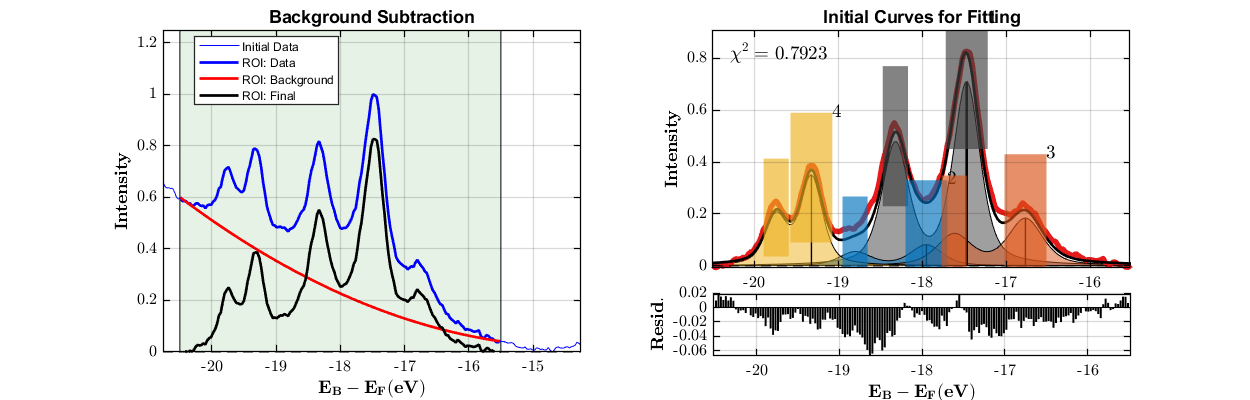


% 5 - Preview the initial conditions of the model vs data f
pes2ncurve_view_init(pes_fit.data{1}, cTYPE, iparams, bTYPE, ibgrnd);

**(C) Execute ARPES fitting algorithm**


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


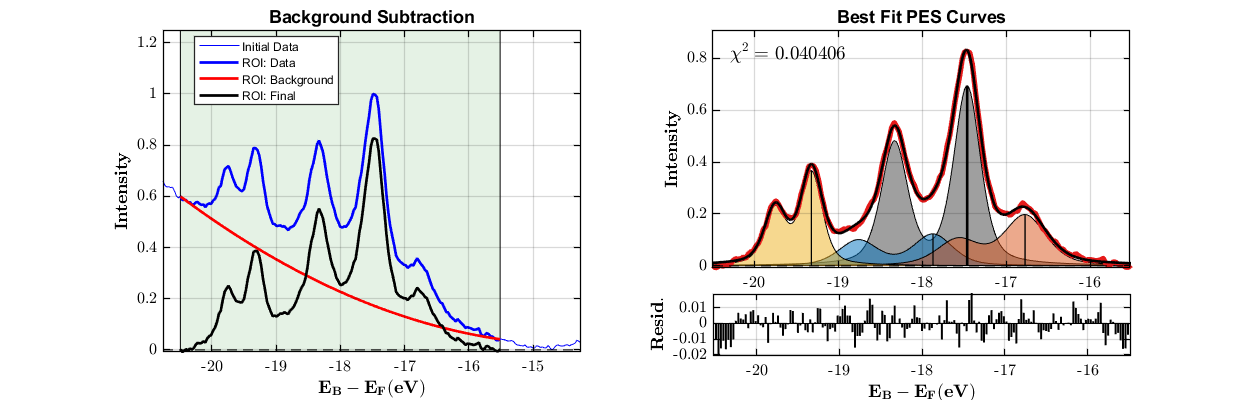

ans = struct with fields:
    solve_type: "fmincon"
         cTYPE: [4×1 string]
       iparams: {[4×8 double]  [4×8 double]  [4×8 double]}
         bTYPE: "Poly"
        ibgrnd: {[-20.5000 -15.5000 2 0.5000 0 0]  [-20.5000 -15.5000 2 0.5000 0 0]  [-20.5000 -15.5000 2 0.5000 0 0]}
       nSTATES: 4
          xdat: [218×1 double]
          ydat: [218×1 double]
             X: [167×1 double]
             D: [167×1 double]
             M: [167×1 double]
             B: [167×1 double]
            DB: [167×1 double]
            MB: [167×1 double]
             R: [167×1 double]
         CHISQ: 0.0404
        MINFUN: 0.0404
           DoF: 24
       bPARAMS: [6×1 double]
           LHS: -20.5000
           RHS: -15.5000
           ORD: 2
           LAM: 0.5000
           DEL: 0
           BGR: 0
            XX: [1000×1 double]
            YY: [1000×1 double]
       cPARAMS: [4×8 double]
           cYY: [1000×4 double]
            BE: [-17.4647 -17.8716 -16.7752 -19.3208]
           INT: [0.68

solve_type  = "fmincon";
tic
for i = 1:length(pes_fit.data)
    pes_fit.fit{i} = pes2ncurve_solver(pes_fit.data{i}, cTYPE, iparams, bTYPE, ibgrnd, solve_type);
    pes2ncurve_view_fit(pes_fit.fit{i}); pes_fit.fit{i}
end

toc

Elapsed time is 76.564796 seconds.


**(D) Printing out the fit information**

for i = 1:length(pes_fit.data)
    info = "";
    info = info + sprintf("CHISQ: \t\t %.3f \n", pes_fit.fit{i}.CHISQ);
    fprintf(info);
    for j = 1:length(pes_fit.fit{i}.BE)
        info = "";
        info = info + sprintf("N: \t\t %i \n", j);
        info = info + sprintf("BE: \t\t %.3f \n", pes_fit.fit{i}.BE(j));
        info = info + sprintf("INT: \t\t %.3f \n", pes_fit.fit{i}.INT(j));
        info = info + sprintf("FWHM: \t\t %.3f \n", pes_fit.fit{i}.FWHM(j));
        info = info + sprintf("MR: \t\t %.3f \n", pes_fit.fit{i}.MR(j));
        info = info + sprintf("LSE: \t\t %.3f \n", pes_fit.fit{i}.LSE(j));
        info = info + sprintf("LSW: \t\t %.3f \n", pes_fit.fit{i}.LSW(j));
        info = info + sprintf("ASY: \t\t %.3f \n\n", pes_fit.fit{i}.ASY(j));
        fprintf(info);
    end
end

CHISQ: 		 0.040 


N: 		 1 
BE: 		 -17.465 
INT: 		 0.684 
FWHM: 		 0.377 
MR: 		 0.455 
LSE: 		 -0.866 
LSW: 		 0.000 
ASY: 		 0.000 

N: 		 2 
BE: 		 -17.872 
INT: 		 0.120 
FWHM: 		 0.550 
MR: 		 0.400 
LSE: 		 -0.891 
LSW: 		 0.000 
ASY: 		 0.000 

N: 		 3 
BE: 		 -16.775 
INT: 		 0.192 
FWHM: 		 0.590 
MR: 		 0.426 
LSE: 		 -0.797 
LSW: 		 0.000 
ASY: 		 0.000 

N: 		 4 
BE: 		 -19.321 
INT: 		 0.356 
FWHM: 		 0.308 
MR: 		 0.453 
LSE: 		 -0.429 
LSW: 		 0.000 
ASY: 		 0.000 



# **Viewing all the best fits and statistical analysis**

**(A) Execute ARPES fitting algorithm**

% Each n_run takes around 1 min to optimise the fit, so it may take a while to run this part
n_runs      = 10;
solve_type  = "fmincon";
for i = 1:length(pes_fit.data)
    [pes_fit.fit{i}, pes_fit.stat{i}]  = pes2ncurve_solver_n_runs(pes_fit.data{i}, cTYPE, iparams, bTYPE, ibgrnd, solve_type, n_runs);
    pes2ncurve_view_fit(pes_fit.fit{i}); pes_fit.fit{i}
end

**(B) Printing out the fit information**

for i = 1:length(pes_fit.data)
    info = "";
    info = info + sprintf("CHISQ: \t\t %.3f \n", pes_fit.fit{i}.CHISQ);
    fprintf(info);
    for j = 1:length(pes_fit.fit{i}.BE)
        info = "";
        info = info + sprintf("N: \t\t %i \n", j);
        info = info + sprintf("BE: \t\t %.3f \n", pes_fit.fit{i}.BE(j));
        info = info + sprintf("INT: \t\t %.3f \n", pes_fit.fit{i}.INT(j));
        info = info + sprintf("FWHM: \t\t %.3f \n", pes_fit.fit{i}.FWHM(j));
        info = info + sprintf("MR: \t\t %.3f \n", pes_fit.fit{i}.MR(j));
        info = info + sprintf("LSE: \t\t %.3f \n", pes_fit.fit{i}.LSE(j));
        info = info + sprintf("LSW: \t\t %.3f \n", pes_fit.fit{i}.LSW(j));
        info = info + sprintf("ASY: \t\t %.3f \n\n", pes_fit.fit{i}.ASY(j));
        fprintf(info);
    end
end

**(C) Viewing all of the best fits for all the runs performed**

The slider bar here can be used to explore through all of the best fit solutions. 

This is very useful when it comes to trying to find the best 'meaningful' solution, or to determine which parameters can be constrained further, if they are giving results that are not matched well with the data.

nScan = 1; nFit = 5; 
pes2ncurve_view_fit(pes_fit.stat{nScan}.fit{nFit}); pes_fit.stat{nScan}.fit{nFit}

**(D) Plotting a statistical analysis of al lthe fit parameters**

Here, we plot how each fit parameter varies as a function of the run number.

nScan = 1;
view_stat_params(pes_fit.stat{nScan}.params, pes_fit.stat{nScan}.params_label); pes_fit.stat{nScan}

**(E) Plotting a histogram analysis of all fit parameters**

Here, we plot a histogram of each fit parameter, which will reflect the statistical model associated with the fit variable. There are two general forms the histogram may take:

- A **Normal Distribution, **which peaks in the middle and gradually decreases towards both ends of axis. This is usually associated with experimental uncertainties in measurements, so we should expect each variable to yield a Normal distribution.

- A **Uniform Distribution, **which stays constants and where all points in range are equally likely to occur. 

nScan = 1;
nParam = 2;
fprintf(pes_fit.stat{nScan}.params_label{nParam});
view_stat_hist(pes_fit.stat{nScan}.params{nParam}, {'Comp1', 'Comp2', 'Comp3', 'Comp4'});

**(F) Plotting a cluster analysis of all the fit parameters**

Here, we plot a cluster analysis of each fit parameter, so we can identify if there is only a single physical solution, or if there are multiple 'clusters' of solutions. A best fit 2D Gaussian distribution is used to fit the cluster data.

nScan = 1;
nParam = 1; 
fprintf(pes_fit.stat{nScan}.params_label{nParam}); 
view_stat_cluster(pes_fit.stat{nScan}.params{nParam}, {'Comp1', 'Comp2', 'Comp3', 'Comp4'});